Stress testing - notes:

- Are we testing the models' ability to recover parameter values

- Are we testing the limits of what can be modeled

Stimulated data:

- Randomized stimulus - simulated responses (demo)

- Balanced, so there are equal 1's and 0's [DONE]

1) Simulating stimulus:

% number of different experimental phases:
n_phases = 2;

% probability of phases (must be equal to the number of phases):
prob = [0.7 0.9];

% n_trails for learning and neutral conditions
l_learning = 50;
l_neutral = 25;

% empty placeholder
traj_learning = [];
traj_neutral = [];

% simulating stimuli for each phases
for i = 1:n_phases
    % shuffling positions
    pos_l = randperm(l_learning);
    pos_n = randperm(l_neutral);
    
    % simulating 1's and 0's from binominal distribution with different
    % probabilities
    tl_temp1 = binornd(1, prob(i), l_learning, 1);
    tn_temp1 = binornd(1, 0.5, l_neutral, 1);
    
    % abs and -1 creates a mirrored set and the pos-argument randomises the
    % sequence
    tl_temp2 = abs(tl_temp1(pos_l) - 1);
    tn_temp2 = abs(tn_temp1(pos_n) - 1);
    
    % collecting the trajectories for learning and neutral phases
    traj_learning = [traj_learning, tl_temp1, tl_temp2];
    traj_neutral = [traj_neutral, tn_temp1, tn_temp2];
end

% random sequences for assembling the different phases
pos_l = randperm(n_phases*2);
pos_n = randperm(n_phases*2);

sim_stimuli = [];

for i = 1:(n_phases*2)
    sim_stimuli = [sim_stimuli; traj_learning(:,pos_l(i)); traj_neutral(:,pos_n(i))];
end

Now we have a balanced trajectory with multiple phases that varies in probability.

2) Simulating responses:

sim_response = tapas_simModel(sim_stimuli,...
    'tapas_hgf_binary',...
    [NaN 0 1 NaN 1 1 NaN 0 0 1 1 NaN -2.5 -6],...
    'tapas_unitsq_sgm',...
    5,...
    123456789);

Ignored trials: none


3) Fit model:

ehgf_binary_config_dev = tapas_ehgf_binary_config();
ehgf_binary_config_round = tapas_ehgf_binary_config_round();
unitsq_sgm_config = tapas_unitsq_sgm_config();
optim_config_dev = tapas_quasinewton_optim_config();


ehgf_dev_round_optim = tapas_fitModel_round(sim_response.u, ...
    sim_stimuli, ...
    ehgf_binary_config_round, ...
    unitsq_sgm_config, ...
    optim_config_dev);

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [NaN 0 1]
    sa_0: [NaN 0.1000 1]
     rho: [NaN 0 0]
      ka: [1 1]
      om: [NaN 0.0601 3.6250]

 
Parameter estimates for the observation model:
    ze: 0.8357

Model quality:
    LME (more is better): -196.1494
    AIC (less is better): 359.2768
    BIC (less is better): 370.3882
 
    AIC and BIC are approximations to -2*LME = 392.2987.
 


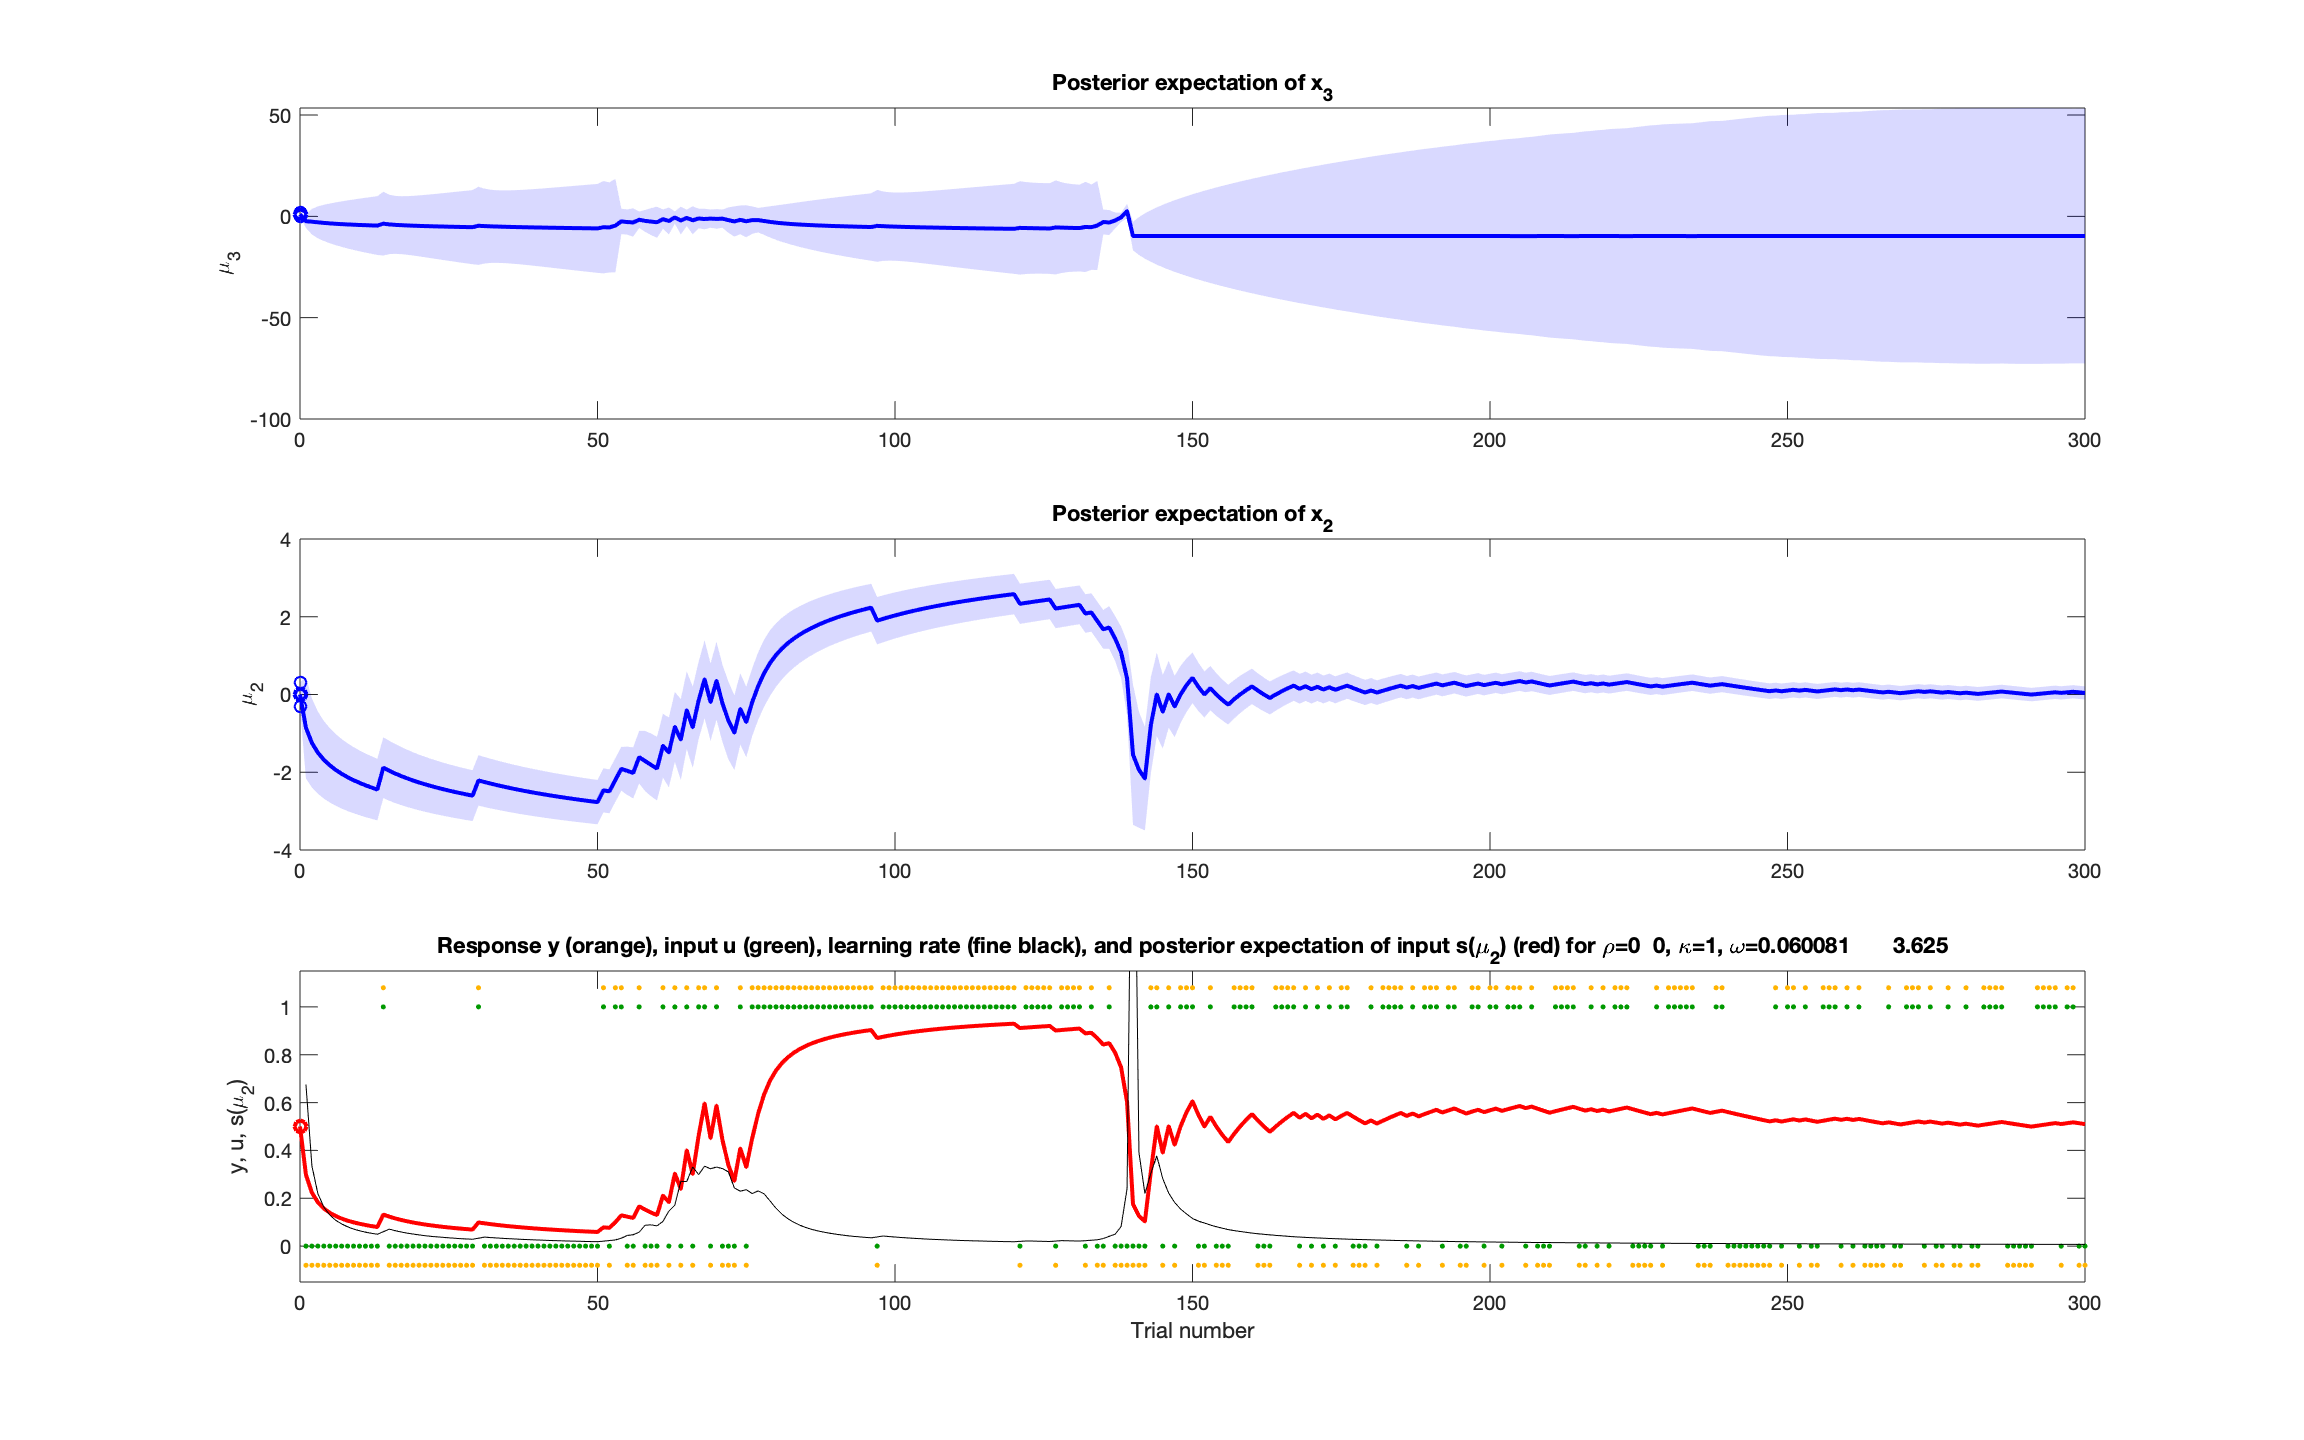


tapas_ehgf_binary_plotTraj(ehgf_dev_round_optim)